f = @(t,y) -3*y

f = function_handle with value:
    @(t,y)-3*y


y0 = 1

y0 = 1

t0 = 0

t0 = 0

tf = 2

tf = 2

h = 0.05

h = 0.0500

[t, y]=odeABM4(f, y0, t0, tf, h)

t =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000


y =     1.0000    0.8607    0.7408    0.6376         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


t =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000


y =     1.0000    0.8607    0.7408    0.6376    0.5488    0.4724    0.4066    0.3499    0.3012    0.2592    0.2231    0.1920    0.1653    0.1423    0.1225    0.1054    0.0907    0.0781    0.0672    0.0578    0.0498    0.0428    0.0369    0.0317    0.0273    0.0235    0.0202    0.0174    0.0150    0.0129    0.0111    0.0096    0.0082    0.0071    0.0061    0.0052    0.0045    0.0039    0.0033    0.0029    0.0025


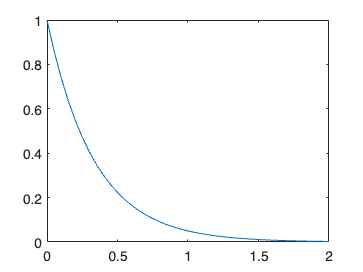


plot(t, y)

function [t, y] = odeABM4(f, yo, to, tf, h)
    steps = 4;
    t = to:h:tf;
    n = length(t);
    y = zeros(size(t));
    fv = zeros(size(y));

    [t(1:steps), y(:,1:steps)] = odeRK4(f, yo, to, to+(steps-1)*h, h)
    
    fm3 = f(t(1),y(1));
    fm2 = f(t(2),y(2));
    fm1 = f(t(3),y(3));
    fm = f(t(4),y(4));

    for i=4:n-1
        %predictor
        y(i+1) = y(i) + h*((55/24)*fm - (59/24)*fm1 + (37/24)*fm2 - (9/24)*fm3);
        %corrector
        y(i+1) = y(i) + h*((9/24)*f(t(i+1),y(i+1)) + (19/24)*fm - (5/24)*fm1 + (1/24)*fm2);
        fm3 = fm2;
        fm2 = fm1;
        fm1 = fm;
        fm = f(t(i+1),y(i+1));
    end

end

function [t,y]=odeRK4(f,y0,t0,tf,h)
    t=t0:h:tf;
    n=length(t);
    m=length(y0);
    y=zeros(m,n);
    y(:,1)=y0;
    for i=1:n-1
        k1=f(t(i),y(:,i));
        k2=f(t(i)+0.5*h,y(:,i)+0.5*k1*h);
        k3=f(t(i)+0.5*h,y(:,i)+0.5*k2*h);
        k4=f(t(i)+h,y(:,i)+k3*h);
        phi=(k1+2*k2+2*k3+k4)/6;
        y(:,i+1)=y(:,i)+phi*h;
    end
end